close all; clear; clc;

# Test Name

**file name**: CP_vs_CT_plots.mlx

**keywords:** 

**date of test:** date

**file created by:** date, Edmonds

**last updated on:** YYYYMMDD

**primary purpose:** 

**primary input and output variables: **

calculated/not measured from test stand- motor radius and rho. 

measured from test stand- time, ESC us, Torque, Thrust, input voltage, input current, rotational speed (omega), input power, output power, efficiencies (motor, prop, overall), temp probe (by motor)

**functions:** 

**Notes:** 

## Input Variables

Use Atmospheric Condition Calculator to calculate air density

rboff_1090_1 = xlsread('MEGA_27x88_4b_0090_RBoff_set_1.csv');
rboff_1090_2 = xlsread('MEGA_27x88_4b_0090_RBoff_set_2.csv');
rboff_1090_3 = xlsread('MEGA_27x88_4b_0090_RBoff_set_3.csv');
reg_1090_1 = xlsread('MEGA_27x88_4b_1090_set_1.csv');
reg_1090_2 = xlsread('MEGA_27x88_4b_1090_set_2.csv');
reg_1090_3 = xlsread('MEGA_27x88_4b_1090_set_3.csv');

area = pi * (27/2)^2;

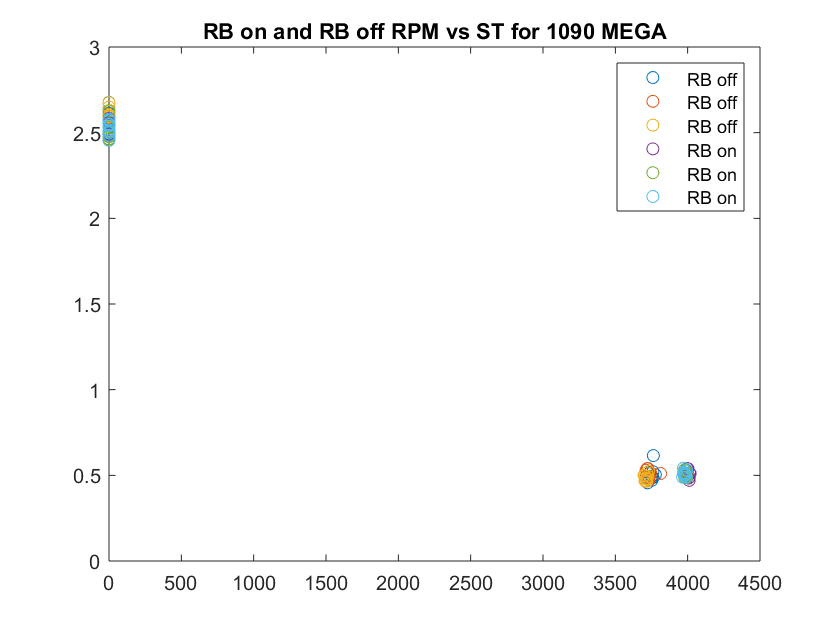

time11 = rboff_1090_1(:,1);                       % [sec]
PWM11 = rboff_1090_1(:,2);                        % [micro sec]
Q11 = rboff_1090_1(:,4);                          % [ft.lbf]
T11 = rboff_1090_1(:,5);                          % [lbf]
Input_V11 = rboff_1090_1(:,6);                    % [Volts]
Input_A11 = rboff_1090_1(:,7);                    % [Amps]
rpm11 = rboff_1090_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad11 = rpm11 .* (pi/30);   % [rad/sec]
P_in_W11 = rboff_1090_1(:,9);                     % [Watts]
P_out_W11 = rboff_1090_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out11 = P_out_W11 .* 0.7478;                  % [ft.lbf/sec]         
P_in11= P_in_W11 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff11 = rboff_1090_1(:,11);                 % [%]
Prop_Eff11 = rboff_1090_1(:,12);                  % [lbf/Watts]
Overall_Eff11 = rboff_1090_1(:,13);               % [lbf/Watts]  
ESC_Temp11 = rboff_1090_1(:,14);                  % [F]
Motor_Temp11 = rboff_1090_1(:,15);                % [F]
disk_loading11 = T11 ./ area;                     % [lb/sq.ft]]
throttle11 = (PWM11 - 1000) ./ 10;
ST11 = rboff_1090_1(:,17); % [s]
Max_Acc11 = rboff_1090_1(:,18);      % [RPM]

time12 = rboff_1090_2(:,1);                       % [sec]
PWM12 = rboff_1090_2(:,2);                        % [micro sec]
Q12 = rboff_1090_2(:,4);                          % [ft.lbf]
T12 = rboff_1090_2(:,5);                          % [lbf]
Input_V12 = rboff_1090_2(:,6);                    % [Volts]
Input_A12 = rboff_1090_2(:,7);                    % [Amps]
rpm12 = rboff_1090_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad12 = rpm12 .* (pi/30);   % [rad/sec]
P_in_W12 = rboff_1090_2(:,9);                     % [Watts]
P_out_W12 = rboff_1090_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out12 = P_out_W12 .* 0.7478;                  % [ft.lbf/sec]         
P_in12 = P_in_W12 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff12 = rboff_1090_2(:,11);                 % [%]
Prop_Eff12 = rboff_1090_2(:,12);                  % [lbf/Watts]
Overall_Eff12 = rboff_1090_2(:,13);               % [lbf/Watts]  
ESC_Temp12 = rboff_1090_2(:,14);                  % [F]
Motor_Temp12 = rboff_1090_2(:,15);                % [F]
disk_loading12 = T12 ./ area;                     % [lb/sq.ft]]
throttle12 = (PWM12 - 1000) ./ 10;
ST12 = rboff_1090_2(:,17); % [s]
Max_Acc12 = rboff_1090_2(:,18);      % [RPM]


time13 = rboff_1090_3(:,1);                       % [sec]
PWM13 = rboff_1090_3(:,2);                        % [micro sec]
Q13 = rboff_1090_3(:,4);                          % [ft.lbf]
T13 = rboff_1090_3(:,5);                          % [lbf]
Input_V13 = rboff_1090_3(:,6);                    % [Volts]
Input_A13 = rboff_1090_3(:,7);                    % [Amps]
rpm13 = rboff_1090_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad13 = rpm13 .* (pi/30);   % [rad/sec]
P_in_W13 = rboff_1090_3(:,9);                     % [Watts]
P_out_W13 = rboff_1090_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out13 = P_out_W13 .* 0.7478;                  % [ft.lbf/sec]         
P_in13 = P_in_W13 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff13 = rboff_1090_3(:,11);                 % [%]
Prop_Eff13 = rboff_1090_3(:,12);                  % [lbf/Watts]
Overall_Eff13 = rboff_1090_3(:,13);               % [lbf/Watts]  
ESC_Temp13 = rboff_1090_3(:,14);                  % [F]
Motor_Temp13 = rboff_1090_3(:,15);                % [F]
disk_loading13 = T13 ./ area;                     % [lb/sq.ft]]
throttle13 = (PWM13 - 1000) ./ 10;
ST13 = rboff_1090_3(:,17); % [s]
Max_Acc13 = rboff_1090_3(:,18);      % [RPM]


time21 = reg_1090_1(:,1);                       % [sec]
PWM21 = reg_1090_1(:,2);                        % [micro sec]
Q21 = reg_1090_1(:,4);                          % [ft.lbf]
T21 = reg_1090_1(:,5);                          % [lbf]
Input_V21 = reg_1090_1(:,6);                    % [Volts]
Input_A21 = reg_1090_1(:,7);                    % [Amps]
rpm21 = reg_1090_1(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad21 = rpm21 .* (pi/30);   % [rad/sec]
P_in_W21 = reg_1090_1(:,9);                     % [Watts]
P_out_W21 = reg_1090_1(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out21 = P_out_W21 .* 0.7478;                  % [ft.lbf/sec]         
P_in21 = P_in_W21 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff21 = reg_1090_1(:,11);                 % [%]
Prop_Eff21 = reg_1090_1(:,12);                  % [lbf/Watts]
Overall_Eff21 = reg_1090_1(:,13);               % [lbf/Watts]  
ESC_Temp21 = reg_1090_1(:,14);                  % [F]
Motor_Temp21 = reg_1090_1(:,15);                % [F]
disk_loading21 = T21 ./ area;                     % [lb/sq.ft]]
throttle21 = (PWM21 - 1000) ./ 10;
ST21 = reg_1090_1(:,17); % [s]
Max_Acc21 = reg_1090_1(:,18);      % [RPM]


time22 = reg_1090_2(:,1);                       % [sec]
PWM22 = reg_1090_2(:,2);                        % [micro sec]
Q22 = reg_1090_2(:,4);                          % [ft.lbf]
T22 = reg_1090_2(:,5);                          % [lbf]
Input_V22 = reg_1090_2(:,6);                    % [Volts]
Input_A22 = reg_1090_2(:,7);                    % [Amps]
rpm22 = reg_1090_2(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad22 = rpm22 .* (pi/30);   % [rad/sec]
P_in_W22 = reg_1090_2(:,9);                     % [Watts]
P_out_W22 = reg_1090_2(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out22 = P_out_W22 .* 0.7478;                  % [ft.lbf/sec]         
P_in22 = P_in_W22 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff22 = reg_1090_2(:,11);                 % [%]
Prop_Eff22 = reg_1090_2(:,12);                  % [lbf/Watts]
Overall_Eff22 = reg_1090_2(:,13);               % [lbf/Watts]  
ESC_Temp22 = reg_1090_2(:,14);                  % [F]
Motor_Temp22 = reg_1090_2(:,15);                % [F]
disk_loading22 = T22 ./ area;                     % [lb/sq.ft]]
throttle22 = (PWM22 - 1000) ./ 10;
ST22 = reg_1090_2(:,17); % [s]
Max_Acc22 = reg_1090_2(:,18);      % [RPM]


time23 = reg_1090_3(:,1);                       % [sec]
PWM23 = reg_1090_3(:,2);                        % [micro sec]
Q23 = reg_1090_3(:,4);                          % [ft.lbf]
T23 = reg_1090_3(:,5);                          % [lbf]
Input_V23 = reg_1090_3(:,6);                    % [Volts]
Input_A23 = reg_1090_3(:,7);                    % [Amps]
rpm23 = reg_1090_3(:,8);              % [RPM]
% convert to RPM for plotting purposes
rad23 = rpm23 .* (pi/30);   % [rad/sec]
P_in_W23 = reg_1090_3(:,9);                     % [Watts]
P_out_W23 = reg_1090_3(:,10);                   % [Watts]
% convert to [ft.lbf/sec]
P_out23 = P_out_W23 .* 0.7478;                  % [ft.lbf/sec]         
P_in23 = P_in_W23 .* 0.7478;                    % [ft.lbf/sec]
Motor_Eff23 = reg_1090_3(:,11);                 % [%]
Prop_Eff23 = reg_1090_3(:,12);                  % [lbf/Watts]
Overall_Eff23 = reg_1090_3(:,13);               % [lbf/Watts]  
ESC_Temp23 = reg_1090_3(:,14);                  % [F]
Motor_Temp23 = reg_1090_3(:,15);                % [F]
disk_loading23 = T23 ./ area;                     % [lb/sq.ft]]
throttle23 = (PWM23 - 1000) ./ 10;
ST23 = reg_1090_3(:,17); % [s]
Max_Acc23 = reg_1090_3(:,18);      % [RPM]


figure(1)
plot(rpm11, ST11, 'o', rpm12, ST21, 'o', rpm13, ST13, 'o',...
    rpm21, ST21, 'o', rpm22, ST22, 'o', rpm23, ST23, 'o');
legend('RB off', 'RB off', 'RB off', 'RB on', 'RB on', 'RB on');
title('RB on and RB off RPM vs ST for 1090 MEGA')